# Validation with Roach et al. (2018) and Roach et al. (2019)

The purpose of this document is to measure the difference between my runs and those documented in Roach et al. (2018) and Roach et al. (2019).

% Initialisation
clear all
close all
addpath functions
addpath packages/bedmap2_toolbox_v4
filename = '/Users/noahday/GitHub/CICE-plotting-tools/cases/pancake_tracer/history/iceh.2005-09.nc';
%ncdisp(filename)
% 
grid = 'gx1';
sector = "SH";
[lat, lon, row] = grid_read(grid);
case_name = 'pancake_tracer';

NFSD = ncread(filename,"NFSD");
NCAT = ncread(filename,"NCAT");
Nf = 16;
Nc = 5;
lims = [6.65000000e-02,   5.31030847e+00,   1.42865861e+01,   2.90576686e+01, 5.24122136e+01,   8.78691405e+01,   1.39518470e+02,   2.11635752e+02, 3.08037274e+02,   4.31203059e+02,   5.81277225e+02,   7.55141047e+02, 9.45812834e+02,   1.34354446e+03,   1.82265364e+03,   2.47261361e+03,  3.35434988e+03];
floe_rad_l = [lims(1:Nf)]; % Floe radius lower bound
floe_rad_h = lims(2:Nf+1); % Floe radius higher bound
floe_binwidth = floe_rad_h - floe_rad_l;
floe_rad_c = (floe_rad_l+floe_rad_h)/2;
thick_rad_l = [0; NCAT(1:end-1)]; % Thickness lower bound
thick_rad_h = NCAT(1:end); % Floe radius higher bound
thick_binwidth = thick_rad_h - thick_rad_l; 
thick_binwidth(end) = 15;


### Figure 1. Circumpolar represtative radii in March and September

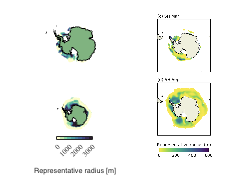

clear filename
f1 = figure;
sector = "SH";
% Reproduce 
filename.march = strcat('cases/',case_name,'/history/iceh.2005-03.nc');
fsdrad_march = data_format_sector(filename.march,"fsdrad",sector);
filename.sep = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
fsdrad_sep = data_format_sector(filename.sep,"fsdrad",sector);
% Apply 1% Mask
SIC = 0.01;
temp = data_format_sector(filename.march,"aice",sector);
ice_mask(:,:) = temp > 0.01;
temp(~ice_mask(:,:)) = NaN;
aice(:,:) = temp;
fsdrad_march(~ice_mask(:,:)) = NaN;
temp = data_format_sector(filename.sep,"aice",sector);
ice_mask(:,:) = temp > 0.01;
temp(~ice_mask(:,:)) = NaN;
aice(:,:) = temp;
fsdrad_sep(~ice_mask(:,:)) = NaN;

max_rad = 3000;
subplot(2,2,1)
[w, a, ~] = map_plot(fsdrad_march,"fsdrad","SHplainnocbar"); 
cmocean('deep',10)
caxis([0,3000]);
subplot(2,2,3)
[w, a, ~] = map_plot(fsdrad_sep,"fsdrad","SHplain"); 
cmocean('deep',10)
a.Location = 'southoutside';
a.Label.String = 'Representative radius [m]';
%a.Ticks = [0,200,400,600];
a.Ticks = [0,1000,2000,3000];
caxis([0,3000]);

subplot(2,2,[2,4])
imshow(imread("observations/roach_2018/fig1.png"))

clear temp w output_data fsdrad_march fsdrad_sep aice icemask max_rad filename

### Figure 2. Number distribution and number distribution tendencies per FSD process

f2 = figure;
subplot(4,2,[5,8])
imshow(imread("observations/roach_2018/fig2.png"))

### Figure 3. Change in representative radius per day per FSD process

f3 = figure;
subplot(10,2,[11,20])
imshow(imread("observations/roach_2018/fig3.png"))

### Model output: NEMO-CICE with an emergent sea ice floe size distribution (https://zenodo.org/record/1193930#.Ysyyly8Rojc)

#### Areal FSD (u-ai251i.1m.0046-0065.areal_fsd_m.nc)

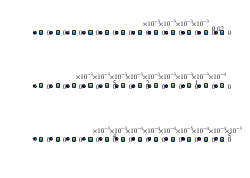

% Mapping the areal FSD data from Roach et al. 2018
filename = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.areal_fsd_m.nc";
sector = "SH";
afsd_t = ncread(filename,"areal_fsd_m");
% time is in months
% take the last september
afsd_roach(:,:,:) = afsd_t(:,:,:,237); 
NFSD12 = NFSD(1:12);
lat_roach19 = ncread(filename,"TLAT");
lon_roach19 = ncread(filename,"TLON");
filename = "/Volumes/NoahDay5TB/roach_2019/cice_FSDv2_LR_2000-2014.nc";
afsd_t = ncread(filename,"areal_fsd");
afsd_roach19(:,:,:) = afsd_t(:,:,:,177); % Last September
NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
NFSD_roach19 = ncread(filename,"NFSD");
NFSD12 = NFSD(1:12);
lat_roach19 = ncread(filename,"TLAT");
lon_roach19 = ncread(filename,"TLON");

figure
[lat, lon, row] = grid_read(grid);
filename = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
afsd = data_format_sector(filename,"afsd",sector);
for i = 1:12
   afsd12(:,:,i) = afsd(:,:,i).*NFSD(i);
end
for nf = 1:4
    afsd12(:,:,12) = afsd12(:,:,12)+ afsd(:,:,12+nf).*NFSD(nf);
end
for i = 1:12
    subplot(3,12,i)
    w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach),double(lon_roach),afsd_roach(:,:,i).*NFSD_roach18(i));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
            %if i == 12
                a = colorbar;
            %end
            %caxis([0,0.3]);

    subplot(3,12,12 + i)
    w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),afsd12(:,:,i).*NFSD12(i));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
            %if i == 12
                a = colorbar;
            %end
            %caxis([0,0.3]);
    
    % FSD-WAVEv2
    subplot(3,12,24 + i)
    w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach19),double(lon_roach19),afsd_roach19(:,:,i));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
            %if i == 12
                a = colorbar;
            %end
            %caxis([0,0.3]);
end

% Calculate the circumpolar FSDs for comparison
% Method:
% 1. Take AFSD and apply a 1% ice mask
% 2. Sum over all cells
% 3. Plot the distributions in terms of 1/m
clear temp
filename_roach18 = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.areal_fsd_m.nc";
filename_roach19 = "/Volumes/NoahDay5TB/roach_2019/cice_FSDv2_LR_2000-2014.nc";
filename = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
filename2 = "/Users/noahday/GitHub/CICE-plotting-tools/cases/monthnoforce/history/iceh.2005-09.nc";
filename3 = "/Users/noahday/GitHub/CICE-plotting-tools/cases/wimoff/history/iceh.2005-09-01.nc";

[lat, lon, row] = grid_read(grid);
NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
NFSD_roach19 = ncread(filename_roach19,"NFSD");
NFSD12 = NFSD(1:12);
lat_roach18 = ncread(filename_roach18,"TLAT");lon_roach18 = ncread(filename_roach18,"TLON");
lat_roach19 = ncread(filename_roach19,"TLAT");lon_roach19 = ncread(filename_roach19,"TLON");

afsd_t = ncread(filename_roach18,"areal_fsd_m");% time is in months take the last september
afsd_roach18(:,:,:) = afsd_t(:,:,:,237); 
afsd_t = ncread(filename_roach19,"areal_fsd");
afsd_roach19(:,:,:) = afsd_t(:,:,:,177); % Last September

afsd2 = data_format_sector(filename2,"afsd","SH");
afsd3 = data_format_sector(filename3,"afsd","SH");

fsd_dist.roach18 = integrate_afsd_hemi(lat_roach18,NFSD_roach18',afsd_roach18);

data_out =     0.0778    0.0065    0.0011    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004


fsd_dist.roach19 = integrate_afsd_hemi(lat_roach19,NFSD_roach19,afsd_roach19);

data_out =     0.0564    0.0063    0.0014    0.0004    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005


fsd_dist.cice = integrate_afsd_hemi(lat,NFSD,afsd);

data_out =     0.1003    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003


fsd_dist.cice2 = integrate_afsd_hemi(lat,NFSD,afsd2);

data_out =     0.1565    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


fsd_dist.cice3 = integrate_afsd_hemi(lat,NFSD,afsd3);

data_out =     0.0509    0.0123    0.0051    0.0025    0.0014    0.0008    0.0005    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001



disp("Data formatting completed.")

Data formatting completed.


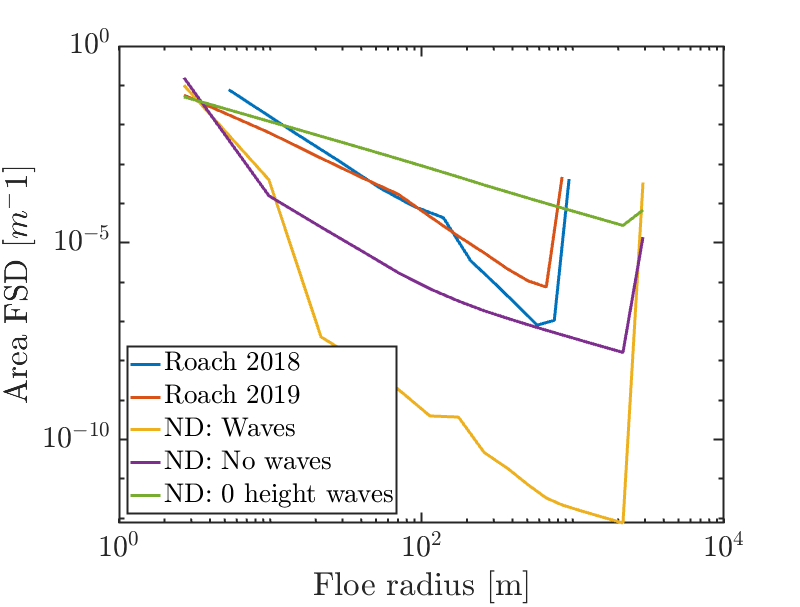

conFigure(30)
f1 = figure;
loglog(NFSD_roach18,fsd_dist.roach18,'LineWidth',3)
hold on
loglog(NFSD_roach19,fsd_dist.roach19,'LineWidth',3)
loglog(NFSD,fsd_dist.cice,'LineWidth',3)
loglog(NFSD,fsd_dist.cice2,'LineWidth',3)
loglog(NFSD,fsd_dist.cice3,'LineWidth',3)
xlabel('Floe radius [m]')
ylabel('Area FSD [$m^-1$]')
legend('Roach 2018','Roach 2019','ND: Waves','ND: No waves','ND: 0 height waves','Location','southwest')
hold off

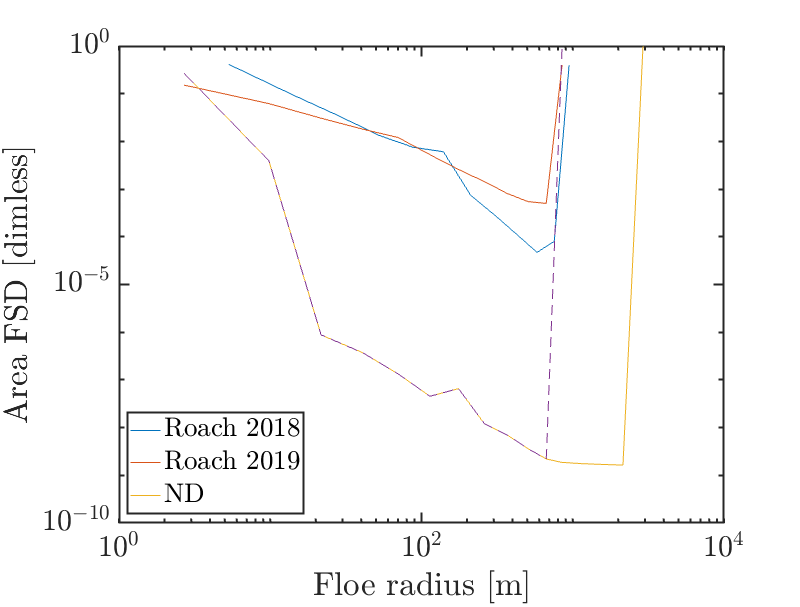


fsd_dist.cice12(:) = fsd_dist.cice(1:12).*NFSD(1:12)';
fsd_dist.cice12(12) = fsd_dist.cice12(12) + sum(fsd_dist.cice(13:16).*NFSD(13:16)');

f2 = figure;
loglog(NFSD_roach18,fsd_dist.roach18.*NFSD_roach18)
hold on
loglog(NFSD_roach19,fsd_dist.roach19.*NFSD_roach19')
loglog(NFSD,fsd_dist.cice.*NFSD')
loglog(NFSD(1:12),fsd_dist.cice12,'--')
xlabel('Floe radius [m]')
ylabel('Area FSD [dimless]')
legend('Roach 2018','Roach 2019','ND','Location','southwest')


% aice_bar = [mean(aice_roach18(ice_mask_roach18)),mean(aice_roach19(ice_mask_roach19)),mean(aice(ice_mask))];
% f3 = figure;
% bar(aice_bar)

#### Change in FSD due to waves

filename_roach18_wave = "/Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.dafsdwave_m.nc";
ncdisp(filename_roach18_wave)

Source:
           /Volumes/NoahDay5TB/roach_2018/u-ai251i.1m.0046-0065.dafsdwave_m.nc
Format:
           classic
Global Attributes:
           CDI                      = 'Climate Data Interface version 1.9.0 (http://mpimet.mpg.de/cdi)'
           Conventions              = 'CF-1.6'
           history                  = 'Wed Mar 07 21:48:14 2018: cdo select,name=dafsdwave_m u-ai251i.1m.0046-0065.nc u-ai251i.1m.0046-0065.dafsdwave_m.nc
                                      Wed Mar  7 21:40:13 2018: ncrcat u-ai251i.1d.2024-01.nc u-ai251i.1d.2024-02.nc u-ai251i.1d.2024-03.nc u-ai251i.1d.2024-04.nc u-ai251i.1d.2024-05.nc u-ai251i.1d.2024-06.nc u-ai251i.1d.2024-07.nc u-ai251i.1d.2024-08.nc u-ai251i.1d.2024-09.nc u-ai251i.1d.2024-10.nc u-ai251i.1d.2024-11.nc u-ai251i.1d.2024-12.nc u-ai251i.1d.2025-01.nc u-ai251i.1d.2025-02.nc u-ai251i.1d.2025-03.nc u-ai251i.1d.2025-04.nc u-ai251i.1d.2025-05.nc u-ai251i.1d.2025-06.nc u-ai251i.1d.2025-07.nc u-ai251i.1d.2025-08.nc u-ai251i.1d.2025-09.nc u-ai251

NFSD_roach18 = [5.31030845642089844 14.2865858078002930 29.0576686859130859 52.4122123718261719 87.8691406250000000 139.518463134765625 211.635757446289062 308.037261962890625 431.203063964843750 581.277221679687500 755.141052246093750 945.81280517578125];
lat_roach18 = ncread(filename_roach18,"TLAT");lon_roach18 = ncread(filename_roach18,"TLON");
dafsd_t = ncread(filename_roach18_wave,"dafsdwave_m");% time is in months take the last september
dafsd_roach18(:,:,:) = dafsd_t(:,:,:,237); 
[test,afsd,aice,dafsd] = integrate_afsd_hemi(lat_roach18,NFSD_roach18',dafsd_roach18); % dafsd_wave.roach18

data_out =      0     0     0     0     0     0     0     0     0     0     0     0


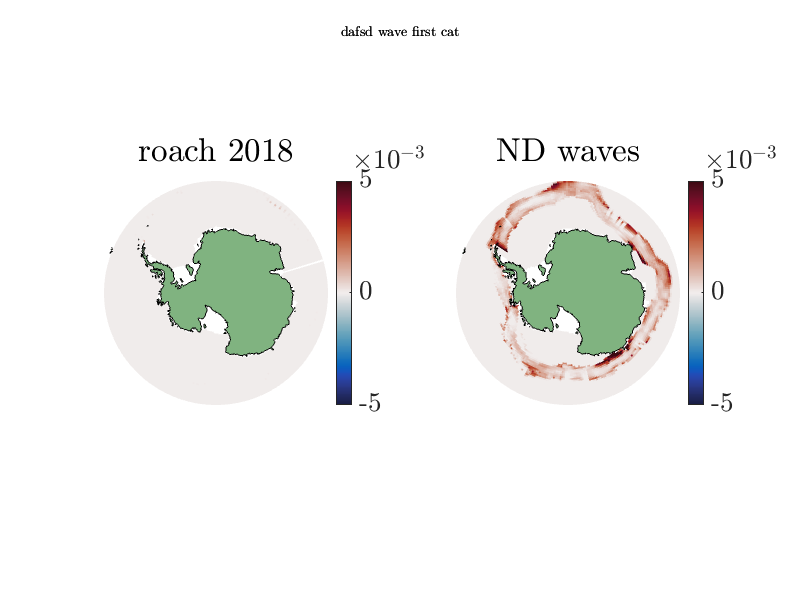

[data_out] = dfsdrad(lat_roach18,NFSD_roach18',dafsd_roach18);


filename = strcat('cases/',case_name,'/history/iceh.2005-09.nc');
dafsd_wave = data_format_sector(filename,"dafsd_wave","SH");
%dafsd_wave.ndwave = integrate_afsd_hemi(lat,NFSD,dafsd_wave);
[dafsd_wave_ra] = dfsdrad(lat,NFSD,dafsd_wave);

figure;   
subplot(1,2,1)
title('roach 2018')
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach18),double(lon_roach18),dafsd_roach18(:,:,1).*NFSD_roach18(1));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-0.005,0.005])
                cmocean('balance,10')
subplot(1,2,2)
title('ND waves')
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),dafsd_wave(:,:,1).*NFSD(1));
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-0.005,0.005])
                cmocean('balance,10')
sgtitle('dafsd wave first cat') 

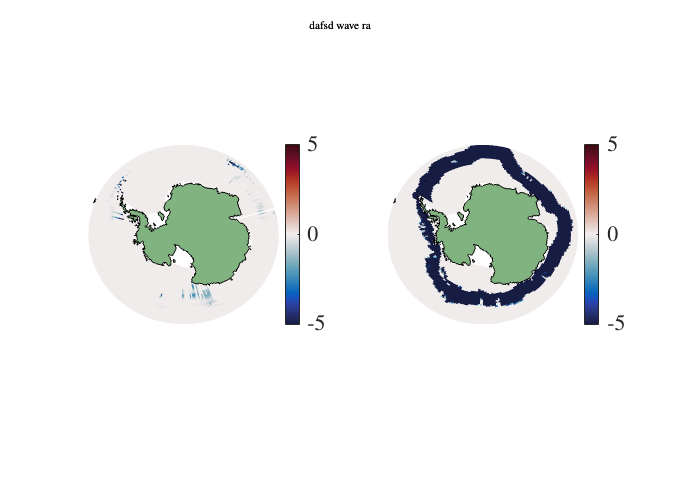


figure;   
subplot(1,2,1)
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat_roach18),double(lon_roach18),data_out);
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-5,5])
                cmocean('balance,10')
subplot(1,2,2)
w = worldmap('world');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90,-55]);
            setm(w, 'maplonlimit', [-180,180]);
            setm(w, 'meridianlabel', 'off')
            setm(w, 'parallellabel', 'off')
            setm(w, 'mlabellocation', 60);
            setm(w, 'plabellocation', 10);
            setm(w, 'mlabelparallel', -45);
            setm(w, 'mlinelimit', [-90 -40]);
            setm(w, 'grid', 'off');
            %setm(w, 'frame', 'on');
            setm(w, 'labelrotation', 'on')
            pcolorm(double(lat),double(lon),dafsd_wave_ra);
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
                a = colorbar;
                caxis([-5,5])
                cmocean('balance,10')
sgtitle('dafsd wave ra') 

data_out =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Unable to perform assignment because dot indexing is not supported for variables of this type.


conFigure(30)
f1 = figure;
loglog(NFSD_roach18,dafsd_wave.roach18 ,'LineWidth',3)
hold on
loglog(NFSD,dafsd_wave.ndwave ,'LineWidth',3)
xlabel('Floe radius [m]')
ylabel('Area FSD [$m^-1$]')
legend('Roach 2018','ND: Waves','ND: No waves','ND: 0 height waves','Location','southwest')
hold off

## Roach et al. (2019)

### Figure 2. Circumpolar represtative radii in Winter

figure;
sector = "SH";
% Reproduce Currently winter == AUGUST
filename.sep = strcat('cases/',case_name,'/history/iceh.2005-08.nc');
fsdrad_sep = data_format_sector(filename.sep,"fsdrad",sector);
% Apply 1% Mask
SIC = 0.01;
temp = data_format_sector(filename.sep,"aice",sector);
ice_mask(:,:) = temp > 0.01;
temp(~ice_mask(:,:)) = NaN;
aice(:,:) = temp;
fsdrad_sep(~ice_mask(:,:)) = NaN;

max_rad = 3000;
subplot(1,5,1)
[w, a, ~] = map_plot(fsdrad_sep,"fsdrad","SHplain"); 
cmocean('deep',10)
a.Location = 'southoutside';
a.Label.String = 'Representative radius [m]';
%a.Ticks = [0,200,400,600];
a.Ticks = [0,100,200,300,400,500,600];
caxis([0,600]);

subplot(1,5,[2,5])
imshow(imread("observations/roach_2019/fig2.png"))

clear temp w a output_data fsdrad_march fsdrad_sep aice icemask max_rad filename

### Model output: CICE experiments with varying floe and wave physics (https://zenodo.org/record/3463580#.Ysyymi8Rojc)

## Functions

function [data_out,afsd,aice,dafsd] = integrate_afsd_hemi(lat,NFSD,afsd)

    [len,wid] = size(lat);
    % Calculate aice
    for i = 1:len
        for j = 1:wid
            temp(:) = afsd(i,j,:);
            aice(i,j) = sum(temp.*NFSD');
            clear temp
        end
    end
    clear len wid
    
    % Define ice masks
    SIC = 0.01; % 1% ice mask
    ice_mask = aice > SIC;
    SH_mask = lat < 0;
    
    % Apply ice masks
    
    for i = 1:length(NFSD)
        temp(:,:) = afsd(:,:,i).*SH_mask;
        temp(~ice_mask) = NaN;
        afsd(:,:,i) = temp;
        temp2 = temp(ice_mask);
        idx = isnan(temp2);
        fsd_int(i) = mean(temp(ice_mask));
        dafsd = temp2(~idx);
        if numel(idx) == numel(temp2)
            fsd_int(i) = 0;
        else
            fsd_int(i) = mean(temp2(~idx));
        end
        clear temp temp2
    end

    data_out = fsd_int
end





function [data_out] = dfsdrad(lat,NFSD,afsd)

    [len,wid] = size(lat);
    % Calculate aice
    for i = 1:len
        for j = 1:wid
            temp(:) = afsd(i,j,:);
            fsdrad(i,j) = sum(temp.*NFSD'.*NFSD');
            clear temp
        end
    end
    clear len wid
    
    % Define ice masks
    SIC = eps; % 1% ice mask
    ice_mask = fsdrad > SIC;
    SH_mask = lat < 0;
    
    % Apply ice masks
    temp(:,:) = fsdrad(:,:).*SH_mask;
    %temp(~ice_mask) = NaN;


    data_out = temp;
end